# Laborator 08

## P1

f = @(x) cos(x);
d = -sin([0,2*pi]);
t = linspace(0,2*pi,200)';
x = [0,pi/2,pi,3*pi/2,2*pi]; 
y = f(x);


## Spline complete

fprintf("Coeficicientii pentru Spline complete: ");

Coeficicientii pentru Spline complete: 

c1 = CubicSplinec(x,y,0,d);
disp(c1);

   0.129006137732798  -0.405284734569351  -0.000000000000000   1.000000000000000
   0.129006137732798   0.202642367284676  -0.954929658551372   0.000000000000000
  -0.129006137732798   0.405284734569351  -0.000000000000000  -1.000000000000000
  -0.129006137732798  -0.202642367284676   0.954929658551372  -0.000000000000000



g = @(x) (x .^ 3)

g = function_handle with value:
    @(x)(x.^3)


d = 3 .* (x .^ 2)

Unrecognized function or variable 'x'.

x = [-1, 0, 1];
y = g(x);
c2 = CubicSplinec(x, y, 0, d);

## Spline cu derivate secunde

fprintf("Coeficicientii pentru Spline cu derivate secunde: ");

Coeficicientii pentru Spline cu derivate secunde: 

d2 = -cos([0,2*pi]);
c2 = CubicSplinec(x,y,1,d2);
disp(c2);

   0.099559626155111  -0.343612104938479  -0.096875140087956   1.000000000000000
   0.138821641592027   0.187224209876957  -0.930710873529383   0.000000000000000
  -0.138821641592027   0.405284734569351  -0.000000000000000  -1.000000000000000
  -0.099559626155111  -0.187224209876957   0.930710873529383  -0.000000000000000



## Spline naturale

fprintf("Coeficicientii pentru Spline naturale: ");

Coeficicientii pentru Spline naturale: 

c3 = CubicSplinec(x,y,2);
disp(c3);

  -0.036858896495085  -0.057897819224193  -0.545674090600784   1.000000000000000
   0.184294482475426   0.115795638448386  -0.818511135901176   0.000000000000000
  -0.184294482475426   0.405284734569351  -0.000000000000000  -1.000000000000000
   0.036858896495085  -0.115795638448386   0.818511135901176  -0.000000000000000



## Spline deBoor

fprintf("Coeficicientii pentru Spline deBoor: ");

Coeficicientii pentru Spline deBoor: 

c4 = CubicSplinec(x,y,3);
disp(c4);

   0.129006137732798  -0.405284734569351   0.000000000000001   1.000000000000000
   0.129006137732798   0.202642367284676  -0.954929658551372   0.000000000000000
  -0.129006137732798   0.405284734569351   0.000000000000000  -1.000000000000000
  -0.129006137732798  -0.202642367284675   0.954929658551372  -0.000000000000000



## P2

s_matlab = spline(x,y,t);
fprintf("Evaluarea Spline-ului din MATLAB:")

Evaluarea Spline-ului din MATLAB:

disp(s_matlab');

   1.000000000000000   0.999398015303151   0.997608303632757   0.994655228619043   0.990563153892236   0.985356443082563   0.979059459820250   0.971696567735524   0.963292130458611   0.953870511619739   0.943456074849133   0.932073183777020   0.919746202033627   0.906499493249181   0.892357421053907   0.877344349078033   0.861484640951786   0.844802660305391   0.827322770769075   0.809069335973065   0.790066719547588   0.770339285122870   0.749911396329137   0.728807416796617   0.707051710155535   0.684668640036119   0.661682570068595   0.638117863883190   0.613998885110130   0.589349997379641   0.564195564321951   0.538559949567286   0.512467516745872   0.485942629487936   0.459009651423705   0.431692946183406   0.404016877397264   0.376005808695507   0.347684103708360   0.319076126066052   0.290206239398807   0.261098807336854   0.231778193510417   0.202268761549725   0.172594875085003   0.142780897746479   0.112851193164378   0.082830124968927   0.052742056790353   0.022611352258883


s1 = evalsplinec(x,c1,t);
fprintf("Evaluarea Spline-ului complet:");

Evaluarea Spline-ului complet:

disp(s1');

   1.000000000000000   0.999600030403780   0.998416364035272   0.996473364524702   0.993795395502296   0.990406820598282   0.986332003442886   0.981595307666333   0.976221096898853   0.970233734770669   0.963657584912010   0.956517010953101   0.948836376524170   0.940640045255443   0.931952380777146   0.922797746719507   0.913200506712751   0.903185024387106   0.892775663372797   0.881996787300052   0.870872759799096   0.859427944500158   0.847686705033462   0.835673405029237   0.823412408117708   0.810928077929101   0.798244778093645   0.785386872241564   0.772378724003086   0.759244697008438   0.746009154887845   0.732696461271535   0.719330979789734   0.705937074072669   0.692539107750565   0.679161444453651   0.665828447812152   0.652564481456295   0.639393909016307   0.626341094122414   0.613430400404842   0.600686191493819   0.588132831019571   0.575794682612324   0.563696109902305   0.551861476519742   0.540315146094859   0.529081482257884   0.518184848639043   0.507649608868564


s2 = evalsplinec(x,c2,t);
fprintf("Evaluarea Spline-ului cu derivate secunde:");

Evaluarea Spline-ului cu derivate secunde:

disp(s2');

   1.000000000000000   0.996601869406014   0.992537444330402   0.987825527242252   0.982484920610655   0.976534426904701   0.969992848593480   0.962878988146081   0.955211648031596   0.947009630719113   0.938291738677724   0.929076774376517   0.919383540284583   0.909230838871012   0.898637472604893   0.887622243955318   0.876203955391375   0.864401409382155   0.852233408396748   0.839718754904243   0.826876251373732   0.813724700274303   0.800282904075047   0.786569665245053   0.772603786253413   0.758404069569215   0.743989317661550   0.729378332999507   0.714589918052177   0.699642875288650   0.684556007178016   0.669348116189364   0.654038004791785   0.638644475454369   0.623186330646205   0.607682372836384   0.592151404493996   0.576612228088130   0.561083646087877   0.545584460962327   0.530133475180569   0.514749491211694   0.499451311524791   0.484257738588951   0.469187574873264   0.454259622846819   0.439492684978707   0.424905563738017   0.410517061593840   0.396345981015265


s3 = evalsplinec(x,c3,t);
fprintf("Evaluarea Spline-ului natural");

Evaluarea Spline-ului natural

disp(s3');

   1.000000000000000   0.982712119073327   0.965301839909087   0.947762201470073   0.930086242719077   0.912267002618891   0.894297520132308   0.876170834222119   0.857879983851119   0.839418007982098   0.820777945577850   0.801952835601166   0.782935717014840   0.763719628781663   0.744297609864428   0.724662699225927   0.704807935828953   0.684726358636299   0.664411006610756   0.643854918715117   0.623051133912174   0.601992691164720   0.580672629435547   0.559083987687448   0.537219804883215   0.515073119985640   0.492636971957516   0.469904399761635   0.446868442360790   0.423522138717773   0.399858527795376   0.375870648556393   0.351551539963614   0.326894240979833   0.301891790567842   0.276537227690433   0.250823591310400   0.224743920390533   0.198291253893626   0.171458630782472   0.144239090019861   0.116625670568588   0.088611411391444   0.060189351451222   0.031352529710713   0.002093985132711  -0.027593243319992  -0.057716116684604  -0.088281595998332  -0.119296642298383


s4 = evalsplinec(x,c4,t);
fprintf("Evaluarea Spline-ului deBoor");

Evaluarea Spline-ului deBoor

disp(s4');

   1.000000000000000   0.999600030403780   0.998416364035272   0.996473364524702   0.993795395502296   0.990406820598282   0.986332003442886   0.981595307666334   0.976221096898853   0.970233734770669   0.963657584912010   0.956517010953102   0.948836376524171   0.940640045255443   0.931952380777147   0.922797746719507   0.913200506712751   0.903185024387106   0.892775663372797   0.881996787300052   0.870872759799097   0.859427944500158   0.847686705033463   0.835673405029237   0.823412408117708   0.810928077929102   0.798244778093645   0.785386872241565   0.772378724003087   0.759244697008438   0.746009154887846   0.732696461271536   0.719330979789734   0.705937074072669   0.692539107750566   0.679161444453652   0.665828447812153   0.652564481456296   0.639393909016307   0.626341094122414   0.613430400404843   0.600686191493820   0.588132831019571   0.575794682612325   0.563696109902306   0.551861476519742   0.540315146094859   0.529081482257884   0.518184848639044   0.507649608868565

## P3

p=[
    0,0;
    0,0.4;
    0,0.6;
    0,0.7;
    0.1,0.75;
    0.2,0.7;
    0.2,0.5;
    0.1,0.4;
    0,0.4;
    0.2, 0.35;
    0.35,0.25;
    0.4,0.05;
    0.4,0.05;
    ];
f=p(:,1);
g=p(:,2);
plot(f,g,'o')
hold on
t=1:length(f);
grid on
axis equal


sf=spline(t,f,1:0.1:length(t));%matlab
%sf=spline(t,[-0.2;f;0],1:0.1:length(t));%matlab
sg=spline(t,g,1:0.1:length(t));

% Spline deBoor
coef_f = CubicSplinec(t,f,3);
coef_g = CubicSplinec(t,g,3);
my_spline_f = evalsplinec(t,coef_f,1:0.1:length(t))'

my_spline_f =                    0  -0.001225707735247  -0.002221172028514  -0.003027024075445  -0.003683895071682  -0.004232416212870  -0.004713218694652  -0.005166933712672  -0.005634192462573  -0.006155626139998                   0   0.000602696068713   0.001029323622970   0.001239251467128   0.001191848405544   0.000846483242574   0.000162524782574  -0.000900658170099  -0.002383696811088  -0.004327222336038                   0  -0.001185076539604  -0.001896122463366  -0.001929981793069  -0.001083498550495   0.000846483242574   0.004063119564355   0.008769566393067   0.015168979706927   0.023464515484152                   0   0.005237610089702   0.011355166230493   0.018180675705147   0.025542145796435   0.033267583787130   0.041184996960004   0.049122392597831   0.056907777983381   0.064369160399429   0.100000000000000   0.112134636180796   0.123675457541392   0.134507278972481   0.144514915364755   0.153583181608907   0.161596892595628   0.168440863215611   0.173999908359548   0.1

my_spline_g = evalsplinec(t,coef_g,1:0.1:length(t))'

my_spline_g =                    0   0.052259070972887   0.101905940768546   0.149048644888842   0.193795218835638   0.236253698110797   0.276532118216184   0.314738514653661   0.350980922925093   0.385367378532343   0.400000000000000   0.427397473389023   0.453263100619454   0.477704917193159   0.500830958612000   0.522749260377841   0.543567857992545   0.563394786957978   0.582338082776001   0.600505780948479   0.600000000000000   0.613251035471023   0.625841656753637   0.637831686338523   0.649280946716364   0.660249260377841   0.670796449813635   0.680982337514429   0.690866745970904   0.700509497673742   0.700000000000000   0.707148384726885   0.713770272365998   0.719818337452748   0.725245254522544   0.730003698110797   0.734046342752914   0.737325862984307   0.739794933340383   0.741406228356552   0.750000000000000   0.751105425621437   0.750677253782371   0.748544963850485   0.744538035193458   0.738485947178972   0.730218179174707   0.719564210548345   0.706353520667565   0.6

sf

sf =                    0  -0.001157989075841  -0.001950297390891  -0.002417556140791  -0.002600396521187  -0.002539449727722  -0.002275346956039  -0.001848719401782  -0.001300198260594  -0.000670414728119                   0   0.000670414728119   0.001300198260594   0.001848719401782   0.002275346956039   0.002539449727722   0.002600396521187   0.002417556140791   0.001950297390891   0.001157989075841                   0  -0.001523669836633  -0.003250495651484  -0.004977321466335  -0.006500991302969  -0.007618349183166  -0.008126239128711  -0.007821505161384  -0.006500991302969  -0.003961541575246                   0   0.005524264618414   0.012501784345344   0.020760566463560   0.030128618255836   0.040433947004943   0.051504559993656   0.063168464504745   0.075253667820984   0.087588177225145   0.100000000000000   0.112326611362976   0.124443358270110   0.136235055612097   0.147586518279627   0.158382561163393   0.168507999154088   0.177847647142404   0.186286320019033   0.1937088326

sg

sg =                    0   0.052079011803114   0.101185704089455   0.147428112360887   0.190914272119274   0.231752218866478   0.270049988104364   0.305915615334796   0.339457136059637   0.370782585780750   0.400000000000000   0.427217414219250   0.452542863940363   0.476084384665204   0.497950011895636   0.518247781133522   0.537085727880726   0.554571887639113   0.570814295910545   0.585920988196886   0.600000000000000   0.613151331319887   0.625442840149092   0.636934348978297   0.647685680298184   0.657756656599434   0.667207100372730   0.676096834108753   0.684485680298184   0.692433461431706   0.700000000000000   0.707227260501203   0.714085775463269   0.720528219421608   0.726507266911629   0.731975592468741   0.736885870628354   0.741190775925877   0.744842982896719   0.747795166076291   0.750000000000000   0.751389626675302   0.751814057997832   0.751102773335272   0.749085252055301   0.745590973525602   0.740449417113854   0.733490062187739   0.724542388114938   0.7134358742

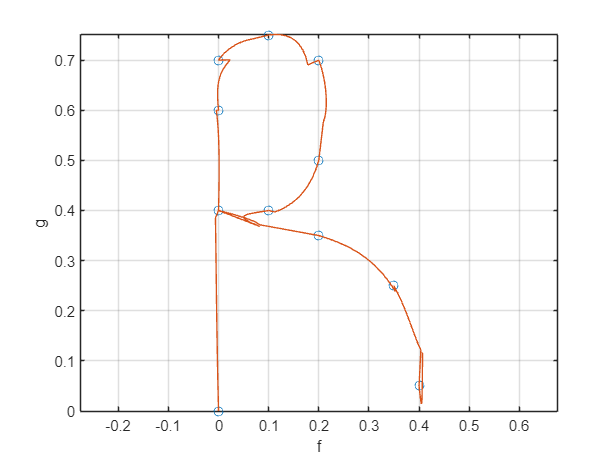


plot(my_spline_f,my_spline_g)
grid on
axis equal
xlabel('f')
ylabel('g')
hold off

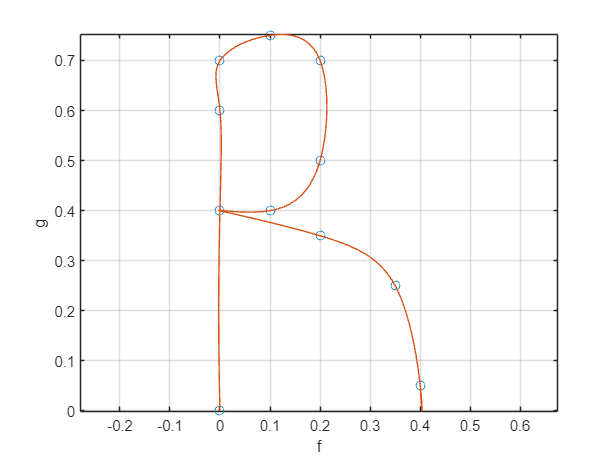


plot(f,g,'o')
hold on
t=1:length(f);
grid on
axis equal
plot(sf,sg)
grid on
axis equal
xlabel('f')
ylabel('g')
hold off